[net,classes] = imagePretrainedNetwork( "googlenet")

net =   dlnetwork with properties:

         Layers: [143×1 nnet.cnn.layer.Layer]
    Connections: [169×2 table]
     Learnables: [116×3 table]
          State: [0×3 table]
     InputNames: {'data'}
    OutputNames: {'prob'}
    Initialized: 1

  View summary with summary.


classes = 1000×1 string array
    "tench"
    "goldfish"
    "great white shark"
    "tiger shark"
    "hammerhead"
    "electric ray"
    "stingray"
    "cock"
    "hen"
    "ostrich"
    "brambling"
    "goldfinch"
    "house finch"
    "junco"
    "indigo bunting"
    "robin"
    "bulbul"
    "jay"
    "magpie"
    "chickadee"
    "water ouzel"
    "kite"
    "bald eagle"
    "vulture"
    "great grey owl"
    "European fire salamander"
    "common newt"
    "eft"
    "spotted salamander"
    "axolotl"


inputSize = net.Layers(1).InputSize

inputSize =    224   224     3


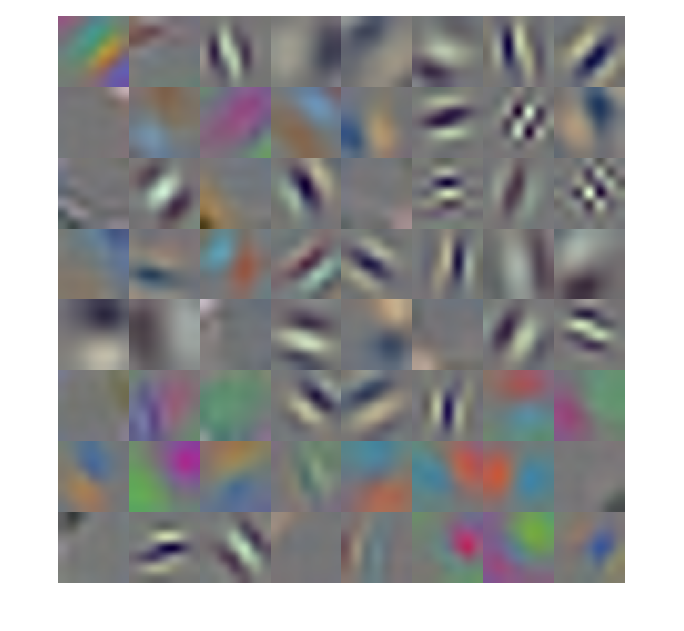

W = net.Layers(2).Weights;
montage(rescale(W))

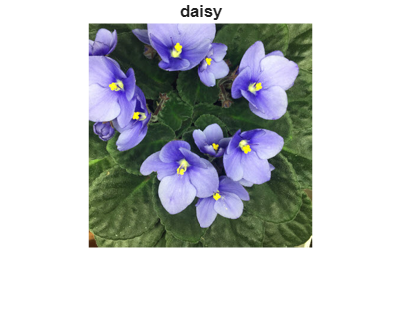

im = imread("violet.jpg");
im = imresize(im,inputSize(1:2));
imshow(im)
title(scores2label(minibatchpredict(net,im),classes))

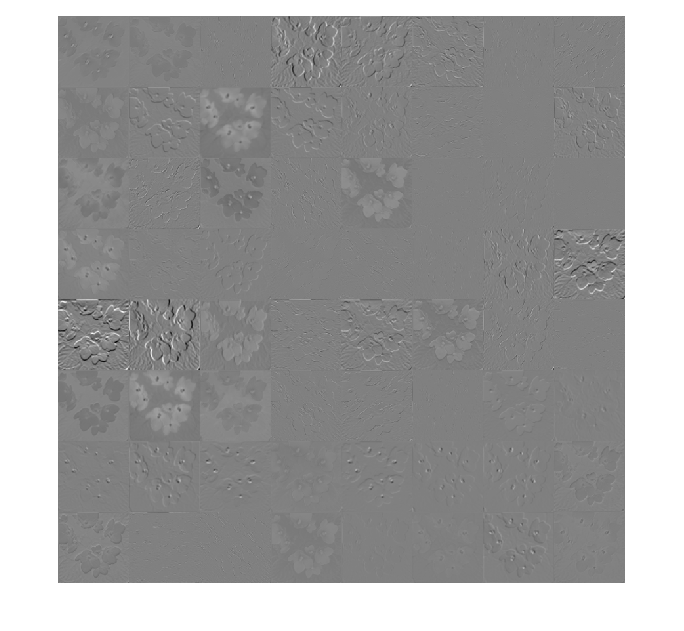

actvn = minibatchpredict(net,im,Outputs=net.Layers(2).Name);
montage(mat2gray(actvn))